# Lab7

# MirHamed Jafarzadeh - 810195374

# Sajjad Pakdaman Savoji - 810195517

## *Part 7 - 1: Initialization of Parameters ("dcl_init.m" Loading)*

clear
close all
clc
dcl_init

## *Part 7 - 2: NonCoherent FSK-Modulation Implementation*

### `I. Channel Simulating with Random Phase`

**1.  Bit Generating**

b_tx = bit_gen(pkt_size, k)

b_tx =      1     0
     1     1
     0     0
     1     0
     1     0
     0     0
     0     1
     1     1
     1     1
     1     0


**2. Bit-to-Symbol Mapping**

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
sym_idx

sym_idx =      4     3     1     4     4     1     2     3     3     4     1     3     3     1     3     1     1     3     4     3     3     1     4     4     4     4     3     1     4     1     3     2     1     2     2     3     4     1     3     1     1     2     4     3     1     1     1     3     3     3


**3. Transmitting Pulse Shaping**

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', mod_det_opt)

tx_smpl =    0.1250 + 0.0000i   0.1196 + 0.0363i   0.1039 + 0.0694i   0.0793 + 0.0966i   0.0478 + 0.1155i   0.0123 + 0.1244i  -0.0244 + 0.1226i  -0.0589 + 0.1102i  -0.0884 + 0.0884i  -0.1102 + 0.0589i  -0.1226 + 0.0244i  -0.1244 - 0.0123i  -0.1155 - 0.0478i  -0.0966 - 0.0793i  -0.0694 - 0.1039i  -0.0363 - 0.1196i  -0.0000 - 0.1250i   0.0363 - 0.1196i   0.0694 - 0.1039i   0.0966 - 0.0793i   0.1155 - 0.0478i   0.1244 - 0.0123i   0.1226 + 0.0244i   0.1102 + 0.0589i   0.0884 + 0.0884i   0.0589 + 0.1102i   0.0244 + 0.1226i  -0.0123 + 0.1244i  -0.0478 + 0.1155i  -0.0793 + 0.0966i  -0.1039 + 0.0694i  -0.1196 + 0.0363i  -0.1250 + 0.0000i  -0.1196 - 0.0363i  -0.1039 - 0.0694i  -0.0793 - 0.0966i  -0.0478 - 0.1155i  -0.0123 - 0.1244i   0.0244 - 0.1226i   0.0589 - 0.1102i   0.0884 - 0.0884i   0.1102 - 0.0589i   0.1226 - 0.0244i   0.1244 + 0.0123i   0.1155 + 0.0478i   0.0966 + 0.0793i   0.0694 + 0.1039i   0.0363 + 0.1196i   0.0000 + 0.1250i  -0.0363 + 0.1196i


**4.  Adding Phase Offset to Channel**

chnl_phase_offset_amb = 2*pi .* rand(1,pkt_size);
temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


phase_noise = kron(chnl_phase_offset_amb, temp)

phase_noise =     3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230    3.1230


rx_smpl = tx_smpl.*exp(1i * phase_noise);

**5.  Channel Simulation With White Gaussian Noise**

**        5.1. Compute Noise Characteristics**

Es_avg = 1;
Eb = Es_avg / log2(M);
EbNo = db2pow(10);
var_noise = 0.5*(Eb/EbNo);

**        5.2. Adding Noise to Signal**

n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
noise_smpl = n_real + 1i*n_imag;
rx_smpl_noise = rx_smpl + noise_smpl;

**6.  Pulse Demodulation**

rx_smpl = rx_smpl_noise(chnl_delay_in_smpl+1:end);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');

**7.  Symbol-to-Bit Conversion**

det_bit = b_gray(det_sym_idx, :);

**8.  SER computation**

ser = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)

ser = 1.3000e-04

**9.  BER computation**

ber = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)

ber = 9.5000e-05

### `II. NonCoherent FSK-Modulation Simulation`

**1.  SER and BER Computations and Plots of ****Simulation**** vs ****MATLAB****:**

**    i. 2-FSK**

M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_2_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent');

chnl_phase_offset_amb_2_fsk = 2*pi .* rand(1,pkt_size);
temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


phase_noise_2_fsk = kron(chnl_phase_offset_amb_2_fsk, temp)

phase_noise_2_fsk =     5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476    5.2476


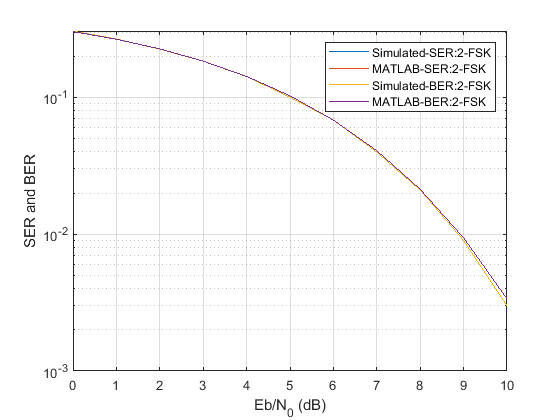

rx_smpl_2_fsk = tx_smpl_2_fsk.*exp(1i * phase_noise_2_fsk);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_2_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_2_fsk./EbNo);

ser_2_fsk = zeros(length(var_noise), 1);
ber_2_fsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_2_fsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_2_fsk = rx_smpl_2_fsk + noise_smpl;
    
    rx_smpl_out_2_fsk = rx_smpl_noise_2_fsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_2_fsk, rx_sym_2_fsk] = pulse_demodulation(rx_smpl_out_2_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_2_fsk = b_gray(det_sym_idx_2_fsk, :);
    
    ser_2_fsk(i) = 1 - sum(det_sym_idx_2_fsk == sym_idx)/length(sym_idx);
    
    ber_2_fsk(i) = 1 - sum(sum(det_bit_2_fsk == b_tx))/size(det_bit_2_fsk, 1)/size(det_bit_2_fsk, 2);
end

[ber_mat_2_fsk, ser_mat_2_fsk] = berawgn(SNR, 'fsk', M, 'noncoherent');

semilogy(SNR, [ser_2_fsk ser_mat_2_fsk ber_2_fsk ber_mat_2_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:2-FSK','MATLAB-SER:2-FSK','Simulated-BER:2-FSK','MATLAB-BER:2-FSK')
grid


ber_2_fsk_zero = ber_2_fsk;

**    ii. 4-FSK**

M = 4;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end

[tx_smpl_4_fsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent');


chnl_phase_offset_amb_4_fsk = 2*pi .* rand(1,pkt_size);
temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


phase_noise_4_fsk = kron(chnl_phase_offset_amb_4_fsk, temp)

phase_noise_4_fsk =     1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665    1.2665


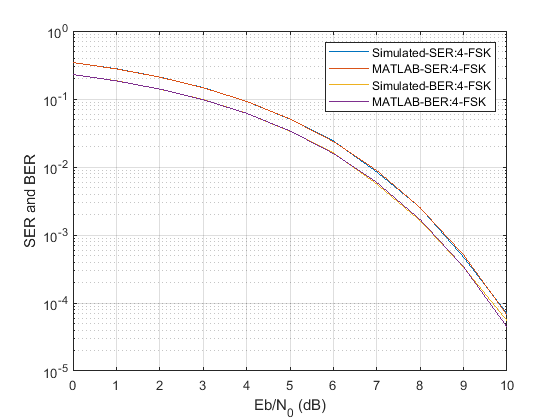

rx_smpl_4_fsk = tx_smpl_4_fsk.*exp(1i * phase_noise_4_fsk);

SNR = (snr_min:snr_step:snr_max)';
Eb_4_fsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_4_fsk./EbNo);

ser_4_fsk = zeros(length(var_noise), 1);
ber_4_fsk = zeros(length(var_noise), 1);
for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_4_fsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_4_fsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_4_fsk = rx_smpl_4_fsk + noise_smpl;
    
    rx_smpl_out_4_fsk = rx_smpl_noise_4_fsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_4_fsk, rx_sym_4_fsk] = pulse_demodulation(rx_smpl_out_4_fsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_4_fsk = b_gray(det_sym_idx_4_fsk, :);
    
    ser_4_fsk(i) = 1 - sum(det_sym_idx_4_fsk == sym_idx)/length(sym_idx);
    
    ber_4_fsk(i) = 1 - sum(sum(det_bit_4_fsk == b_tx))/size(det_bit_4_fsk, 1)/size(det_bit_4_fsk, 2);
end

[ber_mat_4_fsk, ser_mat_4_fsk] = berawgn(SNR, 'fsk', M, 'noncoherent');

semilogy(SNR, [ser_4_fsk ser_mat_4_fsk ber_4_fsk ber_mat_4_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:4-FSK','MATLAB-SER:4-FSK','Simulated-BER:4-FSK','MATLAB-BER:4-FSK')
grid

**    iii. BER Plot for 2-FSK, 4-FSK and 8-FSK**

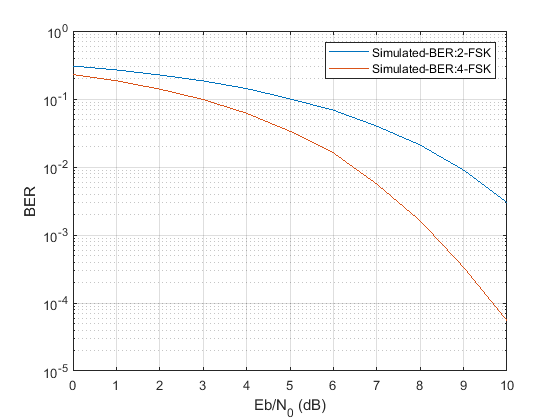

semilogy(SNR, [ber_2_fsk ber_4_fsk])
xlabel('Eb/N_0 (dB)')
ylabel('BER')
legend('Simulated-BER:2-FSK','Simulated-BER:4-FSK')
grid

## *Part 7 - 3: DBPSK-Modulation Implementation*

**1.  Bit Generating**

k = 1;
M = 2^k;
b_tx = bit_gen(pkt_size, 1)

b_tx =      1
     1
     1
     0
     1
     0
     0
     0
     0
     1


**2. Bit Coding**

c_tx = zeros(pkt_size+1, 1); % We assume that first bit is zero
for i=2:pkt_size+1
    c_tx(i) = xor(c_tx(i-1), b_tx(i-1));
end
enc_b_tx = c_tx(2:end)

enc_b_tx =      1
     0
     1
     1
     0
     0
     0
     0
     0
     1


**2. Bit-to-Symbol Mapping**

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
sym_idx_b = zeros(1,pkt_size);
for i=1:M
    indx = enc_b_tx(:,1) == b_gray(i,1);
    indx_b = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & enc_b_tx(:,j) == b_gray(i,j);
        indx_b = indx_b & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
    sym_idx_b(indx_b) = i;
end
sym_idx

sym_idx =      2     1     2     2     1     1     1     1     1     2     1     2     2     1     1     1     1     1     2     1     1     1     1     2     1     1     2     2     1     1     2     1     2     1     2     2     2     1     1     1     1     2     2     2     1     2     1     2     1     1


sym_idx_b

sym_idx_b =      2     2     2     1     2     1     1     1     1     2     2     2     1     2     1     1     1     1     2     2     1     1     1     2     2     1     2     1     2     1     2     2     2     2     2     1     1     2     1     1     1     2     1     1     2     2     2     2     2     1


**3. Transmitting Pulse Shaping**

modulation = 'psk';
pulse_name = 'triangular';
[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent')

tx_smpl =    0.0000 + 0.0000i  -0.0068 + 0.0000i  -0.0135 + 0.0000i  -0.0203 + 0.0000i  -0.0271 + 0.0000i  -0.0338 + 0.0000i  -0.0406 + 0.0000i  -0.0473 + 0.0000i  -0.0541 + 0.0000i  -0.0609 + 0.0000i  -0.0676 + 0.0000i  -0.0744 + 0.0000i  -0.0812 + 0.0000i  -0.0879 + 0.0000i  -0.0947 + 0.0000i  -0.1015 + 0.0000i  -0.1082 + 0.0000i  -0.1150 + 0.0000i  -0.1218 + 0.0000i  -0.1285 + 0.0000i  -0.1353 + 0.0000i  -0.1420 + 0.0000i  -0.1488 + 0.0000i  -0.1556 + 0.0000i  -0.1623 + 0.0000i  -0.1691 + 0.0000i  -0.1759 + 0.0000i  -0.1826 + 0.0000i  -0.1894 + 0.0000i  -0.1962 + 0.0000i  -0.2029 + 0.0000i  -0.2097 + 0.0000i  -0.2165 + 0.0000i  -0.2097 + 0.0000i  -0.2029 + 0.0000i  -0.1962 + 0.0000i  -0.1894 + 0.0000i  -0.1826 + 0.0000i  -0.1759 + 0.0000i  -0.1691 + 0.0000i  -0.1623 + 0.0000i  -0.1556 + 0.0000i  -0.1488 + 0.0000i  -0.1420 + 0.0000i  -0.1353 + 0.0000i  -0.1285 + 0.0000i  -0.1218 + 0.0000i  -0.1150 + 0.0000i  -0.1082 + 0.0000i  -0.1015 + 0.0000i


## *Part 7 - 4: Channel Modeling*

**1.  Adding Delay to Channel**

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed = [delay tx_smpl];

**2.  Adding Phase Noise to Channel**

phase_step = 10/180*pi

phase_step = 0.1745

chnl_phase_offset_amb = (0:phase_step:(pkt_size-1)*phase_step)

chnl_phase_offset_amb = 	1.0e+04 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009


temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


dbpsk_phase_noise = kron(chnl_phase_offset_amb, temp)

dbpsk_phase_noise = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


rx_smpl = tx_smpl_delayed.*exp(1i * dbpsk_phase_noise);

**3.  Channel Simulation With White Gaussian Noise**

**        3.1. Compute Noise Characteristics**

Es_avg = 1;
Eb = Es_avg / log2(M);
EbNo = db2pow(10);
var_noise = 0.5*(Eb/EbNo);

**        3.2. Adding Noise to Signal**

n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
noise_smpl = n_real + 1i*n_imag;
rx_smpl_noise = rx_smpl + noise_smpl;

## *Part 7 - 5: DBPSK-Modulation Reciever Implementation*

**1.  Pulse Demodulation**

rx_smpl = rx_smpl_noise(chnl_delay_in_smpl+1:end);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');

**2.  Symbol-to-Bit Conversion**

det_bit = b_gray(det_sym_idx, :);

**3.  SER computation**

ser = 1 - sum(det_sym_idx == sym_idx_b)/length(sym_idx)

ser = 7.0000e-05

**4.  BER computation**

ber = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)

ber = 7.0000e-05

## *Part 7 - 6: General Claims*

**1.  SER and BER Computations and Plots of ****Simulation**** vs ****MATLAB****:**

**    i. DBPSK**

M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
c_tx = zeros(pkt_size+1, 1); % We assume that first bit is zero
for i=2:pkt_size+1
    c_tx(i) = xor(c_tx(i-1), b_tx(i-1));
end
enc_b_tx = c_tx(2:end);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
sym_idx_b = zeros(1,pkt_size);
for i=1:M
    indx = enc_b_tx(:,1) == b_gray(i,1);
    indx_b = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & enc_b_tx(:,j) == b_gray(i,j);
        indx_b = indx_b & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
    sym_idx_b(indx_b) = i;
end

modulation = 'psk';
pulse_name = 'triangular';
[tx_smpl_dbpsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent')

tx_smpl_dbpsk =    0.0000 + 0.0000i   0.0068 + 0.0000i   0.0135 + 0.0000i   0.0203 + 0.0000i   0.0271 + 0.0000i   0.0338 + 0.0000i   0.0406 + 0.0000i   0.0473 + 0.0000i   0.0541 + 0.0000i   0.0609 + 0.0000i   0.0676 + 0.0000i   0.0744 + 0.0000i   0.0812 + 0.0000i   0.0879 + 0.0000i   0.0947 + 0.0000i   0.1015 + 0.0000i   0.1082 + 0.0000i   0.1150 + 0.0000i   0.1218 + 0.0000i   0.1285 + 0.0000i   0.1353 + 0.0000i   0.1420 + 0.0000i   0.1488 + 0.0000i   0.1556 + 0.0000i   0.1623 + 0.0000i   0.1691 + 0.0000i   0.1759 + 0.0000i   0.1826 + 0.0000i   0.1894 + 0.0000i   0.1962 + 0.0000i   0.2029 + 0.0000i   0.2097 + 0.0000i   0.2165 + 0.0000i   0.2097 + 0.0000i   0.2029 + 0.0000i   0.1962 + 0.0000i   0.1894 + 0.0000i   0.1826 + 0.0000i   0.1759 + 0.0000i   0.1691 + 0.0000i   0.1623 + 0.0000i   0.1556 + 0.0000i   0.1488 + 0.0000i   0.1420 + 0.0000i   0.1353 + 0.0000i   0.1285 + 0.0000i   0.1218 + 0.0000i   0.1150 + 0.0000i   0.1082 + 0.0000i   0.1015 + 0.0000i



delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_dbpsk = [delay tx_smpl_dbpsk];
phase_step = 5/180*pi

phase_step = 0.0873

chnl_phase_offset_amb = (0:phase_step:(pkt_size-1)*phase_step)

chnl_phase_offset_amb = 	1.0e+03 *

         0    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043


temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


dbpsk_phase_noise = kron(chnl_phase_offset_amb, temp)

dbpsk_phase_noise = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


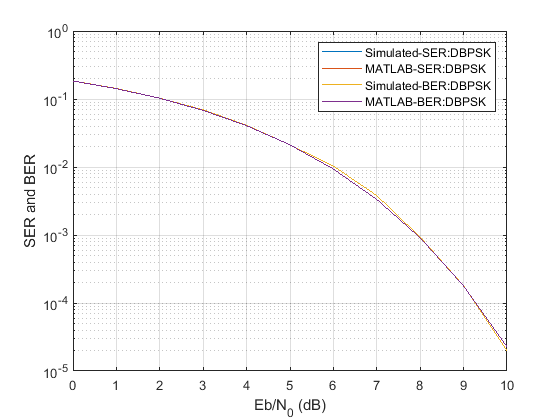

rx_smpl_dbpsk = tx_smpl_delayed_dbpsk.*exp(1i * dbpsk_phase_noise);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_dbpsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_dbpsk./EbNo);

ser_dbpsk = zeros(length(var_noise), 1);
ber_dbpsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_dbpsk = rx_smpl_dbpsk + noise_smpl;
    
    rx_smpl_out_dbpsk = rx_smpl_noise_dbpsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_dbpsk, rx_sym_dbpsk] = pulse_demodulation(rx_smpl_out_dbpsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_dbpsk = b_gray(det_sym_idx_dbpsk, :);
    
    ser_dbpsk(i) = 1 - sum(det_sym_idx_dbpsk == sym_idx_b)/length(sym_idx_b);
    
    ber_dbpsk(i) = 1 - sum(sum(det_bit_dbpsk == b_tx))/size(det_bit_dbpsk, 1)/size(det_bit_dbpsk, 2);
end

[ber_mat_dbpsk, ser_mat_dbpsk] = berawgn(SNR, 'dpsk', M);

semilogy(SNR, [ser_dbpsk ser_mat_dbpsk ber_dbpsk ber_mat_dbpsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:DBPSK','MATLAB-SER:DBPSK','Simulated-BER:DBPSK','MATLAB-BER:DBPSK')
grid

**2.  Effect of Phase Changing on Performance**

**    i. Low Phase Step**

phase_step = 1/180*pi

phase_step = 0.0175


M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
c_tx = zeros(pkt_size+1, 1); % We assume that first bit is zero
for i=2:pkt_size+1
    c_tx(i) = xor(c_tx(i-1), b_tx(i-1));
end
enc_b_tx = c_tx(2:end);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
sym_idx_b = zeros(1,pkt_size);
for i=1:M
    indx = enc_b_tx(:,1) == b_gray(i,1);
    indx_b = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & enc_b_tx(:,j) == b_gray(i,j);
        indx_b = indx_b & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
    sym_idx_b(indx_b) = i;
end

modulation = 'psk';
pulse_name = 'triangular';
[tx_smpl_dbpsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent')

tx_smpl_dbpsk =    0.0000 + 0.0000i   0.0068 + 0.0000i   0.0135 + 0.0000i   0.0203 + 0.0000i   0.0271 + 0.0000i   0.0338 + 0.0000i   0.0406 + 0.0000i   0.0473 + 0.0000i   0.0541 + 0.0000i   0.0609 + 0.0000i   0.0676 + 0.0000i   0.0744 + 0.0000i   0.0812 + 0.0000i   0.0879 + 0.0000i   0.0947 + 0.0000i   0.1015 + 0.0000i   0.1082 + 0.0000i   0.1150 + 0.0000i   0.1218 + 0.0000i   0.1285 + 0.0000i   0.1353 + 0.0000i   0.1420 + 0.0000i   0.1488 + 0.0000i   0.1556 + 0.0000i   0.1623 + 0.0000i   0.1691 + 0.0000i   0.1759 + 0.0000i   0.1826 + 0.0000i   0.1894 + 0.0000i   0.1962 + 0.0000i   0.2029 + 0.0000i   0.2097 + 0.0000i   0.2165 + 0.0000i   0.2097 + 0.0000i   0.2029 + 0.0000i   0.1962 + 0.0000i   0.1894 + 0.0000i   0.1826 + 0.0000i   0.1759 + 0.0000i   0.1691 + 0.0000i   0.1623 + 0.0000i   0.1556 + 0.0000i   0.1488 + 0.0000i   0.1420 + 0.0000i   0.1353 + 0.0000i   0.1285 + 0.0000i   0.1218 + 0.0000i   0.1150 + 0.0000i   0.1082 + 0.0000i   0.1015 + 0.0000i



delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_dbpsk = [delay tx_smpl_dbpsk];

chnl_phase_offset_amb = (0:phase_step:(pkt_size-1)*phase_step)

chnl_phase_offset_amb = 	1.0e+03 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009


temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


dbpsk_phase_noise = kron(chnl_phase_offset_amb, temp)

dbpsk_phase_noise = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


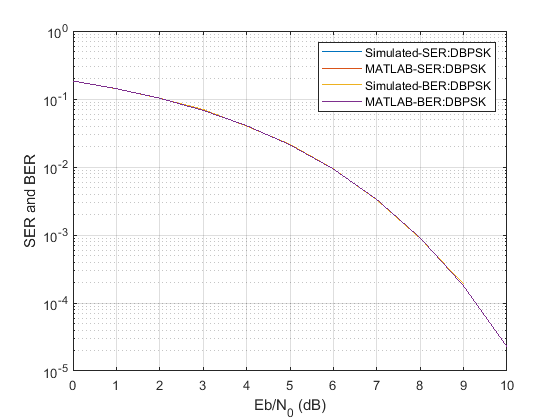

rx_smpl_dbpsk = tx_smpl_delayed_dbpsk.*exp(1i * dbpsk_phase_noise);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_dbpsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_dbpsk./EbNo);

ser_dbpsk = zeros(length(var_noise), 1);
ber_dbpsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_dbpsk = rx_smpl_dbpsk + noise_smpl;
    
    rx_smpl_out_dbpsk = rx_smpl_noise_dbpsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_dbpsk, rx_sym_dbpsk] = pulse_demodulation(rx_smpl_out_dbpsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_dbpsk = b_gray(det_sym_idx_dbpsk, :);
    
    ser_dbpsk(i) = 1 - sum(det_sym_idx_dbpsk == sym_idx_b)/length(sym_idx_b);
    
    ber_dbpsk(i) = 1 - sum(sum(det_bit_dbpsk == b_tx))/size(det_bit_dbpsk, 1)/size(det_bit_dbpsk, 2);
end

[ber_mat_dbpsk, ser_mat_dbpsk] = berawgn(SNR, 'dpsk', M);

semilogy(SNR, [ser_dbpsk ser_mat_dbpsk ber_dbpsk ber_mat_dbpsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:DBPSK','MATLAB-SER:DBPSK','Simulated-BER:DBPSK','MATLAB-BER:DBPSK')
grid

**    ii. Medium Phase Step**

phase_step = 12/180*pi

phase_step = 0.2094


M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
c_tx = zeros(pkt_size+1, 1); % We assume that first bit is zero
for i=2:pkt_size+1
    c_tx(i) = xor(c_tx(i-1), b_tx(i-1));
end
enc_b_tx = c_tx(2:end);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
sym_idx_b = zeros(1,pkt_size);
for i=1:M
    indx = enc_b_tx(:,1) == b_gray(i,1);
    indx_b = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & enc_b_tx(:,j) == b_gray(i,j);
        indx_b = indx_b & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
    sym_idx_b(indx_b) = i;
end

modulation = 'psk';
pulse_name = 'triangular';
[tx_smpl_dbpsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent')

tx_smpl_dbpsk =    0.0000 + 0.0000i  -0.0068 + 0.0000i  -0.0135 + 0.0000i  -0.0203 + 0.0000i  -0.0271 + 0.0000i  -0.0338 + 0.0000i  -0.0406 + 0.0000i  -0.0473 + 0.0000i  -0.0541 + 0.0000i  -0.0609 + 0.0000i  -0.0676 + 0.0000i  -0.0744 + 0.0000i  -0.0812 + 0.0000i  -0.0879 + 0.0000i  -0.0947 + 0.0000i  -0.1015 + 0.0000i  -0.1082 + 0.0000i  -0.1150 + 0.0000i  -0.1218 + 0.0000i  -0.1285 + 0.0000i  -0.1353 + 0.0000i  -0.1420 + 0.0000i  -0.1488 + 0.0000i  -0.1556 + 0.0000i  -0.1623 + 0.0000i  -0.1691 + 0.0000i  -0.1759 + 0.0000i  -0.1826 + 0.0000i  -0.1894 + 0.0000i  -0.1962 + 0.0000i  -0.2029 + 0.0000i  -0.2097 + 0.0000i  -0.2165 + 0.0000i  -0.2097 + 0.0000i  -0.2029 + 0.0000i  -0.1962 + 0.0000i  -0.1894 + 0.0000i  -0.1826 + 0.0000i  -0.1759 + 0.0000i  -0.1691 + 0.0000i  -0.1623 + 0.0000i  -0.1556 + 0.0000i  -0.1488 + 0.0000i  -0.1420 + 0.0000i  -0.1353 + 0.0000i  -0.1285 + 0.0000i  -0.1218 + 0.0000i  -0.1150 + 0.0000i  -0.1082 + 0.0000i  -0.1015 + 0.0000i



delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_dbpsk = [delay tx_smpl_dbpsk];

chnl_phase_offset_amb = (0:phase_step:(pkt_size-1)*phase_step)

chnl_phase_offset_amb = 	1.0e+04 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


dbpsk_phase_noise = kron(chnl_phase_offset_amb, temp)

dbpsk_phase_noise = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


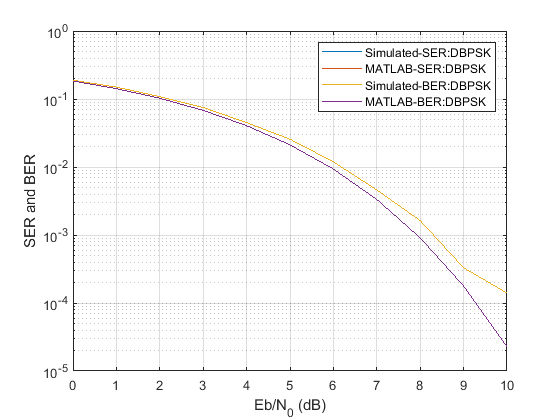

rx_smpl_dbpsk = tx_smpl_delayed_dbpsk.*exp(1i * dbpsk_phase_noise);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_dbpsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_dbpsk./EbNo);

ser_dbpsk = zeros(length(var_noise), 1);
ber_dbpsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_dbpsk = rx_smpl_dbpsk + noise_smpl;
    
    rx_smpl_out_dbpsk = rx_smpl_noise_dbpsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_dbpsk, rx_sym_dbpsk] = pulse_demodulation(rx_smpl_out_dbpsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_dbpsk = b_gray(det_sym_idx_dbpsk, :);
    
    ser_dbpsk(i) = 1 - sum(det_sym_idx_dbpsk == sym_idx_b)/length(sym_idx_b);
    
    ber_dbpsk(i) = 1 - sum(sum(det_bit_dbpsk == b_tx))/size(det_bit_dbpsk, 1)/size(det_bit_dbpsk, 2);
end

[ber_mat_dbpsk, ser_mat_dbpsk] = berawgn(SNR, 'dpsk', M);

semilogy(SNR, [ser_dbpsk ser_mat_dbpsk ber_dbpsk ber_mat_dbpsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:DBPSK','MATLAB-SER:DBPSK','Simulated-BER:DBPSK','MATLAB-BER:DBPSK')
grid

**    iii. High Phase Step**

phase_step = 40/180*pi

phase_step = 0.6981


M = 2;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
c_tx = zeros(pkt_size+1, 1); % We assume that first bit is zero
for i=2:pkt_size+1
    c_tx(i) = xor(c_tx(i-1), b_tx(i-1));
end
enc_b_tx = c_tx(2:end);

if (flg_gray_encode)
    b_gray =  de2bi((0:M-1)',k,'left-msb')
else
    b_gray = gray_code(k)
end

b_gray =      0
     1


sym_idx = zeros(1,pkt_size);
sym_idx_b = zeros(1,pkt_size);
for i=1:M
    indx = enc_b_tx(:,1) == b_gray(i,1);
    indx_b = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & enc_b_tx(:,j) == b_gray(i,j);
        indx_b = indx_b & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
    sym_idx_b(indx_b) = i;
end

modulation = 'psk';
pulse_name = 'triangular';
[tx_smpl_dbpsk, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'conv', 'noncoherent')

tx_smpl_dbpsk =    0.0000 + 0.0000i  -0.0068 + 0.0000i  -0.0135 + 0.0000i  -0.0203 + 0.0000i  -0.0271 + 0.0000i  -0.0338 + 0.0000i  -0.0406 + 0.0000i  -0.0473 + 0.0000i  -0.0541 + 0.0000i  -0.0609 + 0.0000i  -0.0676 + 0.0000i  -0.0744 + 0.0000i  -0.0812 + 0.0000i  -0.0879 + 0.0000i  -0.0947 + 0.0000i  -0.1015 + 0.0000i  -0.1082 + 0.0000i  -0.1150 + 0.0000i  -0.1218 + 0.0000i  -0.1285 + 0.0000i  -0.1353 + 0.0000i  -0.1420 + 0.0000i  -0.1488 + 0.0000i  -0.1556 + 0.0000i  -0.1623 + 0.0000i  -0.1691 + 0.0000i  -0.1759 + 0.0000i  -0.1826 + 0.0000i  -0.1894 + 0.0000i  -0.1962 + 0.0000i  -0.2029 + 0.0000i  -0.2097 + 0.0000i  -0.2165 + 0.0000i  -0.2097 + 0.0000i  -0.2029 + 0.0000i  -0.1962 + 0.0000i  -0.1894 + 0.0000i  -0.1826 + 0.0000i  -0.1759 + 0.0000i  -0.1691 + 0.0000i  -0.1623 + 0.0000i  -0.1556 + 0.0000i  -0.1488 + 0.0000i  -0.1420 + 0.0000i  -0.1353 + 0.0000i  -0.1285 + 0.0000i  -0.1218 + 0.0000i  -0.1150 + 0.0000i  -0.1082 + 0.0000i  -0.1015 + 0.0000i



delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_dbpsk = [delay tx_smpl_dbpsk];

chnl_phase_offset_amb = (0:phase_step:(pkt_size-1)*phase_step)

chnl_phase_offset_amb = 	1.0e+04 *

         0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0013    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0034    0.0034


temp = ones([1, smpl_per_symbl])

temp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


dbpsk_phase_noise = kron(chnl_phase_offset_amb, temp)

dbpsk_phase_noise = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


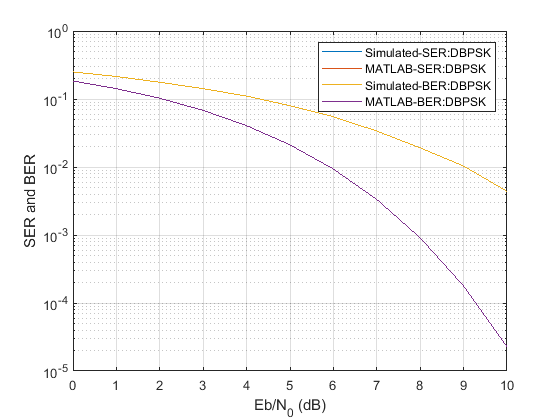

rx_smpl_dbpsk = tx_smpl_delayed_dbpsk.*exp(1i * dbpsk_phase_noise);

SNR = (snr_min:snr_step:snr_max)';
Es_avg = 1;
Eb_dbpsk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_dbpsk./EbNo);

ser_dbpsk = zeros(length(var_noise), 1);
ber_dbpsk = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_dbpsk)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_dbpsk = rx_smpl_dbpsk + noise_smpl;
    
    rx_smpl_out_dbpsk = rx_smpl_noise_dbpsk(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_dbpsk, rx_sym_dbpsk] = pulse_demodulation(rx_smpl_out_dbpsk, modulation, M, fs, smpl_per_symbl, pulse_name, 'correlator', 'noncoherent');
     
    det_bit_dbpsk = b_gray(det_sym_idx_dbpsk, :);
    
    ser_dbpsk(i) = 1 - sum(det_sym_idx_dbpsk == sym_idx_b)/length(sym_idx_b);
    
    ber_dbpsk(i) = 1 - sum(sum(det_bit_dbpsk == b_tx))/size(det_bit_dbpsk, 1)/size(det_bit_dbpsk, 2);
end

[ber_mat_dbpsk, ser_mat_dbpsk] = berawgn(SNR, 'dpsk', M);

semilogy(SNR, [ser_dbpsk ser_mat_dbpsk ber_dbpsk ber_mat_dbpsk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER')
legend('Simulated-SER:DBPSK','MATLAB-SER:DBPSK','Simulated-BER:DBPSK','MATLAB-BER:DBPSK')
grid